**What do the following have in common?...**

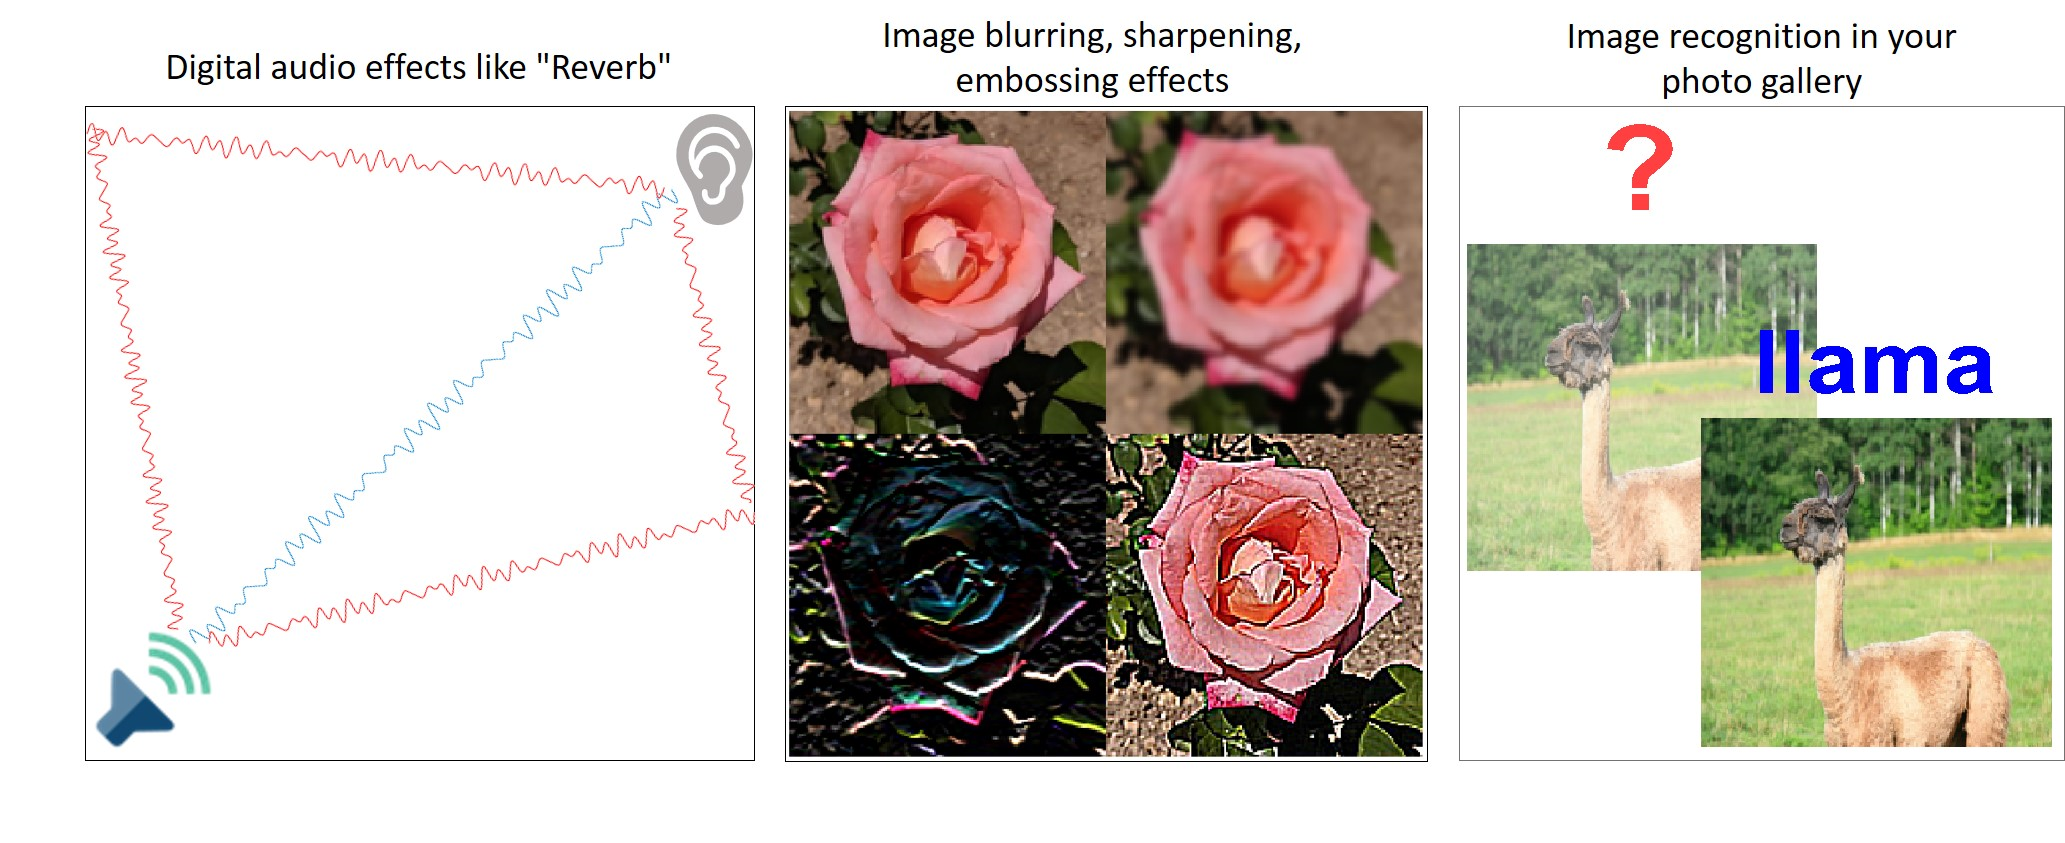

**... it's Convolution! **

# Convolution: Basics

## What is convolution?

The convolution of two continuous signals is another continuous signal. The value at some time `t `is defined as the integral of the products of the two input signals, where one of the signals has been shifted in time by `t` and flipped.

                                    
$$w\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)v\left(t-\tau \right)d\tau$$
  

Let's visualize this process with two simple pulse signals.

% Set up the time step and time (X) axis data.
ts = 1/1000;             % Time step
t = -3:ts:3;             % Time vector


Visit the documentation to learn more about the inputs to these functions: [rectpuls](https://www.mathworks.com/help/signal/ref/rectpuls.html), [tripuls](https://www.mathworks.com/help/signal/ref/tripuls.html)

***Task: ****Use the sliders and dropdowns to set different parameters for the signals. Click ****Run**** to view the convolution process and its result. *

u  = tripuls(t,2,0.9) *2 ; % The first slider sets the width, the second slider scales the amplitude
v  = tripuls(t,2,0.9) *2 ; % The first slider sets the width, the second slider scales the amplitude

 

animateConvolution(u,v,ts,t,-2);

This process is also called **linear convolution.**

***Try***

- *Change *`u`* to a rectangular pulse of width 1.5 and amplitude 1. *

- *Change *`v`* to a triangular pulse of width 1.5 and amplitude 1.*

- *Swap the *`u`* and *`v`* signal settings*`.`

- *Set *`u`* and *`v`* both to triangular pulse with different widths and amplitudes.*

- *Use the third input to set the skewness when using the triangular pulse signals.*

***Reflect***

- *Does the order of inputs matter? Is convolution commutative?*

- *Describe your general observations about the convolution output *`w`* compared to the inputs *`u`* and *`v`*? *

## Compute convolution

The animation above illustrates continuous convolution, which is defined as an integral. This was achieved by approximating a continuous result based on a discrete summation. Discrete convolution is defined by this summation:

                                    
$$w\left(k\right)=\sum_n u\left(n\right)\cdot v\left(k-n\right)$$


You can use the [`conv`](https://www.mathworks.com/help/releases/R2020a/matlab/ref/conv.html) function to compute the discrete convolution of two input sequences or discrete signals.

Let us define two 1-D discrete signals and convolve them using the `conv` function. 

***Task: ****Use the sliders and dropdowns to set different parameters for the two input signals.*

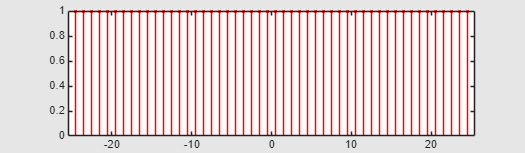

figure("Position",[0 0 1200 350], "Color", [0.9 0.9 0.9]);

L = 50;                   % length of input sequences u and v. Keep it odd for simplicity
n = -(L-1)/2:(L-1)/2;      % X axis data for the signals

u  = rectpuls(n,60);
stem(n,u,"r.")

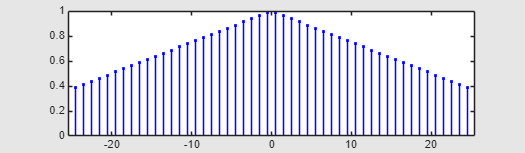

v  = tripuls(n,80);
stem(n,v,"b.")

We use the `conv` function to convolve two vectors in MATLAB.

w  =  conv(u, v);
disp("Output length = " + length(w))

Output length = 99


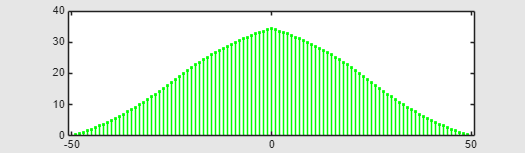

nOut = -(L-1):(L-1);
stem(nOut,w,"g.");

***Reflect***

- *How is the length of convolution output related to the length *`L`* of the two input signals? *

- *What do you think will happen if the input sequences had different lengths? say, *`M`* and *`N`*, instead of *`L`*.*

## **Helper function**

Function for creating the convolution animation.

function animateConvolution(f,h,ts,t,t0)

fs = 1/ts;
Cind = find(t == t0);   % Index of starting point in t
h_center = t0;

% Shift signal to extreme and flip
h = circshift(h,find(t==0) - Cind);
h = fliplr(h);

% Initialize plots for animation
figure("Position",[0 0 1200 350],"Color", [0.9 0.9 0.9]);
title("Continuous Convolution")
xlabel("Time (t and \tau)")
ylabel("Amplitude")

hold on
p0 = plot(t,f,"r","LineWidth",1.2);
p1 = plot(t,h,"b","LineWidth",1.2);
p2 = plot(t0,sum(f.*h)/fs,"g-","LineWidth",1.5);
p3 = area(t,f.*h,"FaceColor","g","FaceAlpha", 0.2,"EdgeColor","k","LineWidth", 1,"ShowBaseLine","off");
p4 = xline(t0, ":k");
legend("u(\tau)","v(t-\tau)","Convolution output w(t)","Area under u(\tau)*v(t-\tau)","Center of v","Location","bestoutside")

xlim([t(1) t(end)]);

% Loop to update plots to visualize the process and result of convolution.
K = fs/20;  % steps to shift the signal in each iteration

while h_center <= abs(t0)
       
    % Convolve
    h = circshift(h,K);    % shift the second signal
    prod = f.*h;           % compute product of the signals
    y = sum(prod)/fs;      % compute integral of product i.e. area under the product    
    h_center = h_center + K/fs;
    
    % Update plots
    p1.YData = h;
    p2.XData = [p2.XData, h_center];
    p2.YData = [p2.YData, y];    
    p3.YData = prod;
    p4.Value = h_center;
    drawnow
    
   
end
hold off

end

Task 3:

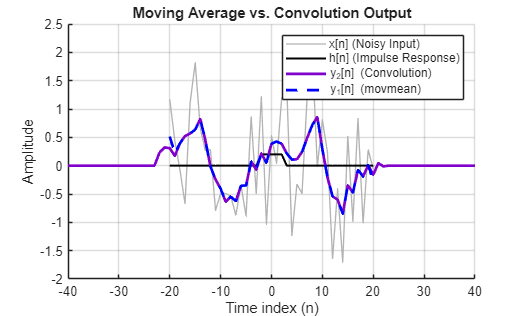

% 5-point moving average
n = -20:20;
z = sin(0.3142 * n);
noise = randn(1, length(n)); 
x = z + noise;
y1 = movmean(x, 5); % We will plot this as Blue

% Calculate the Unit Impulse Response, h[n]
delta = double(n == 0); 
h = movmean(delta, 5); 

% Convolve x[n] with h[n]
y2 = conv(x, h); % We will plot this as Purple
n_y2 = -40:40; 

figure('Name', 'Task 2: All Signals Overlaid');
hold on; 
plot(n, x, 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
plot(n, h, 'k', 'LineWidth', 1.5); 
% (Convolution) as a THICK PURPLE line
plot(n_y2, y2, 'Color', [0.5 0 0.8], 'LineWidth', 2); 
% DASHED BLUE line on top
plot(n, y1, 'b--', 'LineWidth', 2); 

title('Moving Average vs. Convolution Output');
xlabel('Time index (n)');
ylabel('Amplitude');
legend('x[n] (Noisy Input)', 'h[n] (Impulse Response)', 'y_2[n] (Convolution)', 'y_1[n] (movmean)');
grid on;
hold off; % Closes the overlay mode

Task 4:

Task 5:

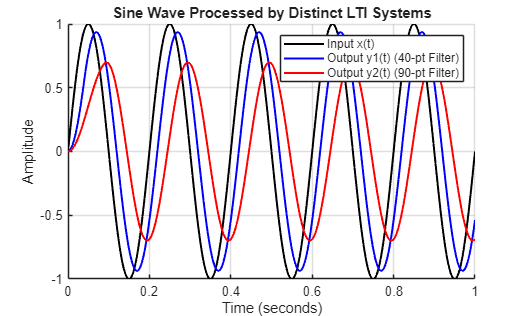

% Generate Input Sine Wave
fs = 1000;             
t = 0:1/fs:1;          
fin = 5;               
x = sin(2 * pi * fin * t); 

% Define two distinct LTI systems 
% System 1: 40-point causal moving average
h1 = ones(1, 40) / 40;  
% System 2: 90-point causal moving average
h2 = ones(1, 90) / 90;  

% Using convolution to process sine wave
y1_full = conv(x, h1);
y2_full = conv(x, h2);

% Truncate the convolution tails so the output arrays match the input time axis 't'
y1 = y1_full(1:length(t));
y2 = y2_full(1:length(t));

% 2. Visualization: Plot input and outputs on the same axes
figure('Name', 'LTI System Frequency Invariance');
hold on;
plot(t, x, 'k', 'LineWidth', 1.5);       
plot(t, y1, 'b', 'LineWidth', 1.5);    
plot(t, y2, 'r', 'LineWidth', 1.5);    

title('Sine Wave Processed by Distinct LTI Systems');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Input x(t)', 'Output y1(t) (40-pt Filter)', 'Output y2(t) (90-pt Filter)', 'Location', 'northeast');
grid on;
hold off;


% The findpeaks function automatically extracts the time locations of the
% crests for Output 1 (y1) and Output 2 (y2)
[pks1, locs1] = findpeaks(y1, t);
[pks2, locs2] = findpeaks(y2, t);

% Calculate Time Period (T) by finding the average time difference between peaks
T1 = mean(diff(locs1)); 
T2 = mean(diff(locs2)); 
f1 = 1 / T1; 
f2 = 1 / T2; 

disp('--- FREQUENCY VERIFICATION ---');

--- FREQUENCY VERIFICATION ---


disp(['Original Input Frequency: ', num2str(fin), ' Hz']);

Original Input Frequency: 5 Hz


disp(['Calculated Output Frequency (System 1): ', num2str(f1), ' Hz']);

Calculated Output Frequency (System 1): 4.9938 Hz


disp(['Calculated Output Frequency (System 2): ', num2str(f2), ' Hz']);

Calculated Output Frequency (System 2): 5 Hz


Task 6:

% --- TASK 6: AUDIO REVERBERATION (LTI SYSTEM) ---

% 1. Load and preview the Impulse Response (Church Balcony)
[IR_audio, F_IR] = audioread('1st_baptist_nashville_balcony.wav');

Error using audioread>readaudio (line 160)
The filename specified was not found in the MATLAB path.

Error in audioread (line 153)
    [y, Fs] = readaudio (filename, fileNameObj.RemoteFileName, range, datatype);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

disp(['Impulse Response Size: ', num2str(size(IR_audio, 1)), ' x ', num2str(size(IR_audio, 2))]);
disp('Playing Church Impulse Response...');
soundsc(IR_audio, F_IR);
pause((length(IR_audio) / F_IR) + 1); % Added a 1-second buffer so sounds don't overlap

% 2. Load and preview the Dry Audio (Ringtone)
[dry_sig, F_dry] = audioread('ringtone.wav');
disp(['Dry Audio Size: ', num2str(size(dry_sig, 1)), ' x ', num2str(size(dry_sig, 2))]);
disp('Playing Dry Ringtone...');
soundsc(dry_sig, F_dry);
pause((length(dry_sig) / F_dry) + 1);

% 3. Extract Stereo Channels from the Impulse Response
left_IR = IR_audio(:, 1);
right_IR = IR_audio(:, 2);

% 4. Apply Convolution (Room Acoustics = LTI System)
disp('Computing convolution to apply reverberation...');
left_reverb = conv(dry_sig, left_IR);
right_reverb = conv(dry_sig, right_IR);

% 5. Recombine into a Stereo Matrix and Play
wet_stereo_sig = [left_reverb, right_reverb];
disp('Playing Processed Stereo Ringtone...');
soundsc(wet_stereo_sig, F_dry);

% 6. Time Vectors and Visualization
t_dry = (0:length(dry_sig)-1) / F_dry;
t_wet = (0:length(wet_stereo_sig)-1) / F_dry;

figure('Name', 'Reverberation Analysis', 'Position', [150, 150, 800, 500]);

% Top Plot: Dry Input
subplot(2,1,1);
plot(t_dry, dry_sig, 'k', 'LineWidth', 1); % Plotted in black
title('Original Input: Dry Ringtone (Mono)');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

% Bottom Plot: Wet Output
subplot(2,1,2);
hold on;
% Using modern RGB color codes instead of basic 'r' and 'b'
plot(t_wet, left_reverb, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); 
plot(t_wet, right_reverb, 'Color', [0.8500 0.3250 0.0980], 'LineStyle', '--'); 
title('Reverberated Output: Church Balcony (Stereo)');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Left Channel', 'Right Channel', 'Location', 'best');
grid on;
hold off;